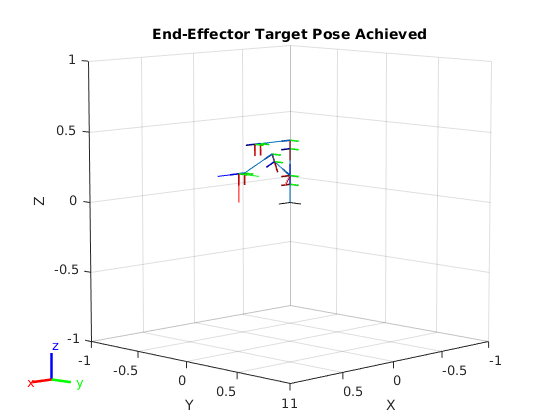

mover6 = importrobot("CPMOVER6.urdf");

X = 0.5;
Y = 0;
Z = 0.25;
A = 0;
B = pi/2;
C = 0;

tform = trvec2tform([X Y Z]) * eul2tform([A B C]);
tform_se3 = se3(tform);

show(mover6, mover6.homeConfiguration);
hold on
plotTransforms(tform_se3, FrameSize=0.2);
title("Initial Guess Configuration and Pose Target")

ik = inverseKinematics("RigidBodyTree", mover6);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = mover6.homeConfiguration;
[configSoln, ~] = ik("link6", tform, weights, initialguess);

show(mover6, configSoln);
title("End-Effector Target Pose Achieved");
hold off;


getTransform(mover6, mover6.homeConfiguration, "link6")

ans =     0.0000         0    1.0000    0.3450
         0    1.0000         0         0
   -1.0000         0    0.0000    0.4425
         0         0         0    1.0000
